## Solver

% add 'controller' and 'kinematic' folders and subfolders to path
parameters;
BusDeclaration;

## No Controller (drop test)

drop = false;
if drop
    X0 = [Init.q,Init.dq]; % X = [x y r thf lf thb lb dx dy dr dthf dlf dthb dlb]
    tspan = [0 Sim.time];
    options = odeset('RelTol',1e-10,'AbsTol',1e-10);
    
    % use ode45 to solve system equations
    sols = ode113(@(t,X) kinematicsNoController(t,X),tspan,X0,options);
end

## Running options

% animate full robot
animate = true;

% run full analysis in data inspector
simulink = false;

% choose which parameters are used
% run based on random sets
run_self = false;

% run based on fits
run_fits = false;

% run based on PSO results
run_PSO = true;

% run based on c PSO results
run_PSO_c = false;

## CPG Controller

if run_self
    Init.q = [0,0.4223,-0.0589,0.6129,0,0.5592,0];
    Init.dq = [1.4129,0,-2.8024,0.4732,0,-0.3224,0];
    Init.CPG = [0.0833,0.8151,-1.1573,0.6409];

    % oscillator parameters
    temp = load("tsw_fits\fit_front.mat","fit_front");
    tswf_fit = temp.fit_front;
    temp = load("tsw_fits\fit_back.mat","fit_back");
    tswb_fit = temp.fit_back;
    
    kx = 0.05;
    tstf = 0.08; tswf = feval(tswf_fit,tstf,kx);
    tstb = 0.0793; tswb = feval(tswb_fit,tstb,kx);
    
    c = [0,-1;1,0];
    % c = [0,0;0,0];

    osc_param = [tstf,tswf,tstb,tswb,kx,c(1,2),c(2,1)];
end
if run_fits
    % change initial placement
    Init.q(2) = 0.5;
    Init.dq(1) = 0.5;
    
    % oscillator parameters
    temp = load("tsw_fits\fit_front.mat","fit_front");
    tswf_fit = temp.fit_front;
    temp = load("tsw_fits\fit_back.mat","fit_back");
    tswb_fit = temp.fit_back;
    
    kx = 0.05;
    tstf = 0.08; tswf = feval(tswf_fit,tstf,kx);
    tstb = 0.0793; tswb = feval(tswb_fit,tstb,kx);
    
    c = [0,-0.5;0.5,0];
    % c = [0,0;0,0];

    osc_param = [tstf,tswf,tstb,tswb,kx,c(1,2),c(2,1)];
end

if run_PSO
    out = load("ExternalSolves/sol.mat");
    BestSol = out.out.BestSol; simParams = out.simParams;
    Init.CPG = [BestSol.Position(1),BestSol.Position(2),BestSol.Position(3),BestSol.Position(4)];
    Init.q(2) = BestSol.Position(5);
    Init.dq(1) = BestSol.Position(9);

    Init.q(4) = th_calc(pi/2 - simParams.kx*BestSol.Position(1),0);
    Init.q(6) = th_calc(pi/2 + simParams.kx*BestSol.Position(3),0);

    [dx_oscf,~] = CPG_Oscillator(Init.CPG(1),Init.CPG(2),1,0,simParams.tst,BestSol.Position(7),simParams.c(1,2),[Init.CPG(3);Init.CPG(4)]);
    Init.dq(4) = dth_calc(pi/2 - simParams.kx*BestSol.Position(1),0,-dx_oscf*simParams.kx,0);
    [dx_oscb,~] = CPG_Oscillator(Init.CPG(3),Init.CPG(4),1,0,BestSol.Position(6),BestSol.Position(8),simParams.c(2,1),[Init.CPG(1);Init.CPG(2)]);
    Init.dq(6) = dth_calc(pi/2 + simParams.kx*BestSol.Position(3),0,dx_oscb*simParams.kx,0);
    
    osc_param = [simParams.tst; BestSol.Position(7); BestSol.Position(6); BestSol.Position(8);  simParams.kx; simParams.c(1,2); simParams.c(2,1)];
    tstf = osc_param(1); tswf = osc_param(2);
    tstb = osc_param(3); tswb = osc_param(4);
    c = simParams.c;
    kx = simParams.kx;
end

if run_PSO_c
    out = load("sol.mat");
    BestSol = out.out.BestSol; simParams = out.simParams;

    c = [0,BestSol.Position(1);-BestSol.Position(1),0];
    Init.CPG = [BestSol.Position(6),BestSol.Position(7),BestSol.Position(8),BestSol.Position(9)];
    Init.q(2) = BestSol.Position(2);
    Init.q(3) = BestSol.Position(3);
    Init.dq(1) = BestSol.Position(4);
    Init.dq(3) = BestSol.Position(5);

    Init.q(4) = th_calc(pi/2 - simParams.kx*BestSol.Position(6),0);
    Init.q(6) = th_calc(pi/2 + simParams.kx*BestSol.Position(8),0);

    tstf = simParams.tstf;
    tstb = simParams.tstb;
    kx = simParams.kx;

    temp = load("tsw_fits\fit_front.mat","fit_front");
    tswf_fit = temp.fit_front;
    temp = load("tsw_fits\fit_back.mat","fit_back");
    tswb_fit = temp.fit_back;
    
    tswf = feval(tswf_fit,tstf,kx);
    tswb = feval(tswb_fit,tstb,kx);

    [dx_oscf,~] = CPG_Oscillator(Init.CPG(1),Init.CPG(2),1,0,tstf,tswf,c(1,2),[Init.CPG(3);Init.CPG(4)]);
    Init.dq(4) = dth_calc(pi/2 - kx*Init.CPG(1),0,-dx_oscf*kx,0);
    [dx_oscb,~] = CPG_Oscillator(Init.CPG(3),Init.CPG(4),1,0,tstb,tswb,c(2,1),[Init.CPG(1);Init.CPG(2)]);
    Init.dq(6) = dth_calc(pi/2 + kx*Init.CPG(3),0,dx_oscb*kx,0);
    
    osc_param = [tstf; tswf; tstb; tswb; BestSol.Position(8);  kx; c(1,2); c(2,1)];
end


X0 = [Init.q,Init.dq,Init.CPG]; % X = [x y r thf lf thb lb dx dy dr dthf dlf dthb dlb]
tspan = [0 Sim.time];
% tspan = [0 (tstf+tswf)];
options = odeset('RelTol',1e-10,'AbsTol',1e-10);
options = odeset('RelTol',1e-6,'AbsTol',1e-6);

% use ode45 to solve system equations
sols = ode113(@(t,X) kinematicsCPG(t,X,osc_param),tspan,X0,options);


## Display Generalised Coordinates

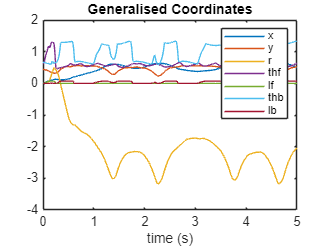

% display state of all variables
plot(sols.x,sols.y(1,:));
hold on
plot(sols.x,sols.y(2,:));
plot(sols.x,sols.y(3,:));
plot(sols.x,sols.y(4,:));
plot(sols.x,sols.y(5,:));
plot(sols.x,sols.y(6,:));
plot(sols.x,sols.y(7,:));
legend('x','y','r','thf','lf','thb','lb');
title("Generalised Coordinates");
xlabel('time (s)');
hold off

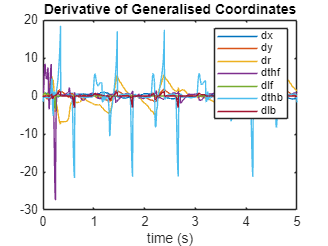


% display derivative state of all variables
plot(sols.x,sols.y(8,:));
hold on
plot(sols.x,sols.y(9,:));
plot(sols.x,sols.y(10,:));
plot(sols.x,sols.y(11,:));
plot(sols.x,sols.y(12,:));
plot(sols.x,sols.y(13,:));
plot(sols.x,sols.y(14,:));
legend('dx','dy','dr','dthf','dlf','dthb','dlb');
title("Derivative of Generalised Coordinates");
xlabel('time (s)');
hold off

## Load into Simulink

if simulink
foot = zeros(8,length(sols.x));
f_end = zeros(2,length(sols.x));
grf_total = zeros(4,length(sols.x));
t_total = zeros(2,length(sols.x));
f_total = zeros(2,length(sols.x));
phi_d_total = zeros(2,length(sols.x));
dphi_d_total = zeros(2,length(sols.x));
th_d_total = zeros(2,length(sols.x));
dth_d_total = zeros(2,length(sols.x));
u = zeros(4,length(sols.x));

for i = 1:length(sols.x)
    x = sols.y(1,i); y = sols.y(2,i); r = sols.y(3,i); 
    thf = sols.y(4,i); lf = sols.y(5,i); thb = sols.y(6,i); lb = sols.y(7,i);
    dx = sols.y(8,i); dy = sols.y(9,i); dr = sols.y(10,i);
    dthf = sols.y(11,i); dlf = sols.y(12,i); dthb = sols.y(13,i); dlb = sols.y(14,i);

    osc = sols.y(15:18,i);
    x_oscf = osc(1); y_oscf = osc(2);
    x_oscb = osc(3); y_oscb = osc(4);
    
    thkf_sols = thk_calc(thf,lf);
    dthkf_sols = dthk_calc(thf,lf,dthf,dlf);
    thaf_sols = tha_calc(thf,lf);
    dthaf_sols = dtha_calc(thf,lf,dthf,dlf);

    thkb_sols = thk_calc(thb,lb);
    dthkb_sols = dthk_calc(thb,lb,dthb,dlb);
    thab_sols = tha_calc(thb,lb);
    dthab_sols = dtha_calc(thb,lb,dthb,dlb);

    foot_dynamics = foot_Func(x,y,r,thf,lf,thkf_sols,thaf_sols,thb,lb,thkb_sols,thab_sols,dx,dy,dr,dthf,dlf,dthkf_sols,dthaf_sols,dthb,dlb,dthkb_sols,dthab_sols);

    foot(:,i) = [foot_dynamics(:,1);foot_dynamics(:,2)];

    grf_f = grf_calc(foot_dynamics(:,1));
    grf_b = grf_calc(foot_dynamics(:,2));

    grf_total(:,i) = [grf_f;grf_b];

    f_end(:,i) = [end_calc(lf,dlf);end_calc(lb,dlb)];

    footf = foot_dynamics(:,1);
    footb = foot_dynamics(:,2);

    %% Front leg controller
    
    uprevf = [0;1];

    % get slip model
    slipf = zeros(4);
    slipf(1) = phi_calc(thf,lf);
    slipf(2) = r_calc(thf,lf);
    slipf(3) = dphi_calc(thf,lf,dthf,dlf);
    slipf(4) = dr_calc(thf,lf,dthf,dlf);

    % update oscilating values
    [dx_oscf,dy_oscf] = CPG_Oscillator(x_oscf,y_oscf,footf(2),footf(4),tstf,tswf,c(1,2),[x_oscb;y_oscb]);

    [phi_df,dphi_df,kpf,kdf,uef,urf,dt_startf] = CPG_states_Hopf_front(sols.x(i),sols.y(:,i),slipf,footf,y_oscf,x_oscf,dx_oscf,kx,uprevf);

    %% Back leg controller

    uprevb = [0;1];

    % get slip model
    slipb = zeros(4);
    slipb(1) = phi_calc(thb,lb);
    slipb(2) = r_calc(thb,lb);
    slipb(3) = dphi_calc(thb,lb,dthb,dlb);
    slipb(4) = dr_calc(thb,lb,dthb,dlb);

    % update oscilating values
    [dx_oscb,dy_oscb] = CPG_Oscillator(x_oscb,y_oscb,footb(2),footb(4),tstb,tswb,c(2,1),[x_oscb;y_oscb]);

    [phi_db,dphi_db,kpb,kdb,ueb,urb,dt_startb] = CPG_states_Hopf_back(sols.x(i),sols.y(:,i),slipb,footb,y_oscb,x_oscb,dx_oscb,kx,uprevb);

    th_df = max(th_calc(phi_df,lf),0);
    if (th_df==0)
        dth_df = max(dth_calc(phi_df,lf,dphi_df,dlf),0);
    else
        dth_df = dth_calc(phi_df,lf,dphi_df,dlf);
    end

    th_db = max(th_calc(phi_db,lb),0);
    if (th_db==0)
        dth_db = max(dth_calc(phi_db,lb,dphi_db,dlb),0);
    else
        dth_db = dth_calc(phi_db,lb,dphi_db,dlb);
    end

    u(:,i) = [uef;urf;ueb;urb];

    % get output
    tf = speedTorque(- kpf*(thf - th_df) - kdf*(dthf - dth_df),dthf);
    ff = F_calc((sols.x(i)-dt_startf),uef,urf,lf,dlf);
    tb = speedTorque(- kpb*(thb - th_db) - kdb*(dthb - dth_db),dthb);
    fb = F_calc((sols.x(i)-dt_startb),ueb,urb,lb,dlb);

    t_total(:,i) = [tf;tb];
    f_total(:,i) = [ff;fb];
    phi_d_total(:,i) = [phi_df;phi_db];
    dphi_d_total(:,i) = [dphi_df;dphi_db];
    th_d_total(:,i) = [th_df;th_db];
    dth_d_total(:,i) = [dth_df;dth_db];
end

% plot(sols.x,foot(1,:));
% hold on
% plot(sols.x,foot(2,:));
% legend('footf_x','footf_y');
% hold off
% 
% plot(sols.x,foot(5,:));
% hold on
% plot(sols.x,foot(6,:));
% legend('footb_x','footb_y');
% hold off
% 
% plot(sols.x,f_end(1,:));
% hold on
% plot(sols.x,f_end(2,:));
% legend('f_endf','f_endb');
% hold off
% 
% plot(sols.x,grf_total(1,:));
% hold on
% plot(sols.x,grf_total(2,:));
% plot(sols.x,grf_total(3,:));
% plot(sols.x,grf_total(4,:));
% legend('grf_nf','grf_tf','grf_nb','grf_tb');
% hold off
% 
% plot(sols.x,t_total)
% legend('torque_f','torque_b');
% 
% plot(sols.x,f_total)
% legend('force_f','force_b');

r_sol = zeros(2,length(sols.x));
dr_sol = zeros(2,length(sols.x));
phi_sol = zeros(2,length(sols.x));
dphi_sol = zeros(2,length(sols.x));

for i = 1:length(sols.x)
    x = sols.y(1,i); y = sols.y(2,i); r = sols.y(3,i); 
    thf = sols.y(4,i); lf = sols.y(5,i); thb = sols.y(6,i); lb = sols.y(7,i);
    dx = sols.y(8,i); dy = sols.y(9,i); dr = sols.y(10,i);
    dthf = sols.y(11,i); dlf = sols.y(12,i); dthb = sols.y(13,i); dlb = sols.y(14,i);
    
    r_sol(:,i) = [r_calc(thf,lf);r_calc(thb,lb)];
    dr_sol(:,i) = [dr_calc(thf,lf,dthf,dlf);dr_calc(thb,lb,dthb,dlb)];
    phi_sol(:,i) = [phi_calc(thf,lf);phi_calc(thb,lb)];
    dphi_sol(:,i) = [dphi_calc(thf,lf,dthf,dlf);dphi_calc(thb,lb,dthb,dlb)];
end

% plot(sols.x,r_sol);
% legend('r_f','r_b');
% plot(sols.x,dr_sol);
% legend('dr_f','dr_b');
% plot(sols.x,phi_sol);
% legend('phi_f','phi_b');
% plot(sols.x,dphi_sol);
% legend('dphi_f','dphi_b');

time = sols.x;
sols_out = transpose(sols.y(1:14,:));
coords_sols.time = transpose(time);
coords_sols.signals.values = sols_out;

system_val = [grf_total;t_total;f_total;foot;u];
system_sols.time = transpose(time);
system_sols.signals.values = transpose(system_val);

template_val = [r_sol(1,:);phi_sol(1,:);dr_sol(1,:);dphi_sol(1,:);r_sol(2,:);phi_sol(2,:);dr_sol(2,:);dphi_sol(2,:)];
template_sols.time = transpose(time);
template_sols.signals.values = transpose(template_val);

setpoint_val = [th_d_total(1,:);dth_d_total(1,:);phi_d_total(1,:);dphi_d_total(1,:);th_d_total(2,:);dth_d_total(2,:);phi_d_total(2,:);dphi_d_total(2,:)];
setpoint_sols.time = transpose(time);
setpoint_sols.signals.values = transpose(setpoint_val);

oscillator_val = [sols.y(15:18,:);repmat(tstf,1,length(sols.x));repmat(tswf,1,length(sols.x));repmat(tstb,1,length(sols.x));repmat(tswb,1,length(sols.x));repmat(kx,1,length(sols.x))];
oscillator_sols.time = transpose(time);
oscillator_sols.signals.values = transpose(oscillator_val);

sim("data_inspector_full.slx");
end

## Animate (drawnow)

lb_f = Spine.RightBody.length; lb_b = Spine.LeftBody.length; 
lf = Femur.length; lt = Tibia.length; lf_o = Femur.offset; lt_o = Tibia.offset;
lp = Piston.length;

if animate
fps = 30; % Desired frame rate
dt = 1 / fps; % Time interval between frames
t_interp = sols.x(1):dt:sols.x(end); % New time vector

% Interpolate all states in sols.y
solsy_interp = interp1(sols.x, sols.y', t_interp, 'linear')';

x_sim = solsy_interp(1,:);
y_sim = solsy_interp(2,:);
r_sim = solsy_interp(3,:);
thf_sim = solsy_interp(4,:);
lf_sim = solsy_interp(5,:);
thkf_sim = thk_calc(thf_sim,lf_sim);
thaf_sim = tha_calc(thf_sim,lf_sim);
thb_sim = solsy_interp(6,:);
lb_sim = solsy_interp(7,:);
thkb_sim = thk_calc(thb_sim,lb_sim);
thab_sim = tha_calc(thb_sim,lb_sim);

x_hipf = x_sim + lb_f*cos(r_sim);
y_hipf = y_sim + lb_f*sin(r_sim);
x_kneef = x_hipf - lf*cos(thf_sim);
y_kneef = y_hipf - lf*sin(thf_sim);
x_footf = x_kneef + lt*cos(thkf_sim);
y_footf = y_kneef - lt*sin(thkf_sim);

x_hipb = x_sim - lb_b*cos(r_sim);
y_hipb = y_sim - lb_b*sin(r_sim);
x_kneeb = x_hipb + lf*cos(thb_sim);
y_kneeb = y_hipb - lf*sin(thb_sim);
x_footb = x_kneeb - lt*cos(thkb_sim);
y_footb = y_kneeb - lt*sin(thkb_sim);

x_piston_topf = x_hipf + lf_o*sin(thf_sim);
y_piston_topf = y_hipf - lf_o*cos(thf_sim);
x_piston_endf = x_piston_topf - lp*cos(thaf_sim);
y_piston_endf = y_piston_topf - lp*sin(thaf_sim);
x_rod_endf = x_piston_endf - (lf_sim).*cos(thaf_sim);
y_rod_endf = y_piston_endf - (lf_sim).*sin(thaf_sim);

x_piston_topb = x_hipb - lf_o*sin(thb_sim);
y_piston_topb = y_hipb - lf_o*cos(thb_sim);
x_piston_endb = x_piston_topb + lp*cos(thab_sim);
y_piston_endb = y_piston_topb - lp*sin(thab_sim);
x_rod_endb = x_piston_endb + (lb_sim).*cos(thab_sim);
y_rod_endb = y_piston_endb - (lb_sim).*sin(thab_sim);

Elapsed time is 19.592241 seconds.


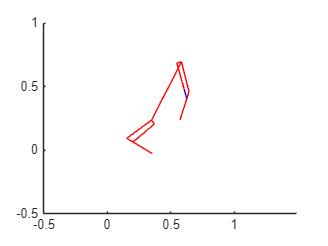

fig = figure;

ax = axes('Parent',fig);

b = animatedline(ax,'Color','r','LineWidth',0.5);
ff = animatedline(ax,'Color','r','LineWidth',0.5);
tf = animatedline(ax,'Color','r','LineWidth',0.5);
fb = animatedline(ax,'Color','r','LineWidth',0.5);
tb = animatedline(ax,'Color','r','LineWidth',0.5);
p_of = animatedline(ax,'Color','r','LineWidth',0.5);
pf = animatedline(ax,'Color','r','LineWidth',0.5);
rf = animatedline(ax,'Color','b','LineWidth',0.5);
p_ob = animatedline(ax,'Color','r','LineWidth',0.5);
pb = animatedline(ax,'Color','r','LineWidth',0.5);
rb = animatedline(ax,'Color','b','LineWidth',0.5);

axes(ax);

axis equal;
axis(ax,[(x_sim(1)-1) (x_sim(1)+1) -0.5 1]);

hold on;
tic
drawnow

for i = 1:width(solsy_interp)

    clearpoints(b);
    clearpoints(ff);
    clearpoints(tf);
    clearpoints(fb);
    clearpoints(tb);
    clearpoints(p_of);
    clearpoints(pf);
    clearpoints(rf);
    clearpoints(p_ob);
    clearpoints(pb);
    clearpoints(rb);

    % body
    addpoints(b,[x_hipf(i), x_hipb(i)],[y_hipf(i), y_hipb(i)]);
    % front femur
    addpoints(ff,[x_hipf(i), x_kneef(i)],[y_hipf(i), y_kneef(i)]);
    % front tibia
    addpoints(tf,[x_kneef(i), x_footf(i)],[y_kneef(i), y_footf(i)]);
    % back femur
    addpoints(fb,[x_hipb(i), x_kneeb(i)],[y_hipb(i), y_kneeb(i)]);
    % back tibia
    addpoints(tb,[x_kneeb(i), x_footb(i)],[y_kneeb(i), y_footb(i)]);
    % front piston offset
    addpoints(p_of,[x_hipf(i), x_piston_topf(i)],[y_hipf(i), y_piston_topf(i)]);
    % front piston
    addpoints(pf,[x_piston_topf(i), x_piston_endf(i)],[y_piston_topf(i), y_piston_endf(i)]);
    % front rod
    addpoints(rf,[x_piston_endf(i), x_rod_endf(i)],[y_piston_endf(i), y_rod_endf(i)]);
    % back piston offset
    addpoints(p_ob,[x_hipb(i), x_piston_topb(i)],[y_hipb(i), y_piston_topb(i)]);
    % back piston
    addpoints(pb,[x_piston_topb(i), x_piston_endb(i)],[y_piston_topb(i), y_piston_endb(i)]);
    % back rod
    addpoints(rb,[x_piston_endb(i), x_rod_endb(i)],[y_piston_endb(i), y_rod_endb(i)]);

    axis(ax,[(x_sim(i)-1) (x_sim(i)+1) -0.5 1]);

    drawnow
    pause(dt);

end
drawnow
toc
hold off;
end

% writeAnimation("KembaMono_hop.gif");